# Fourier Series Approximation

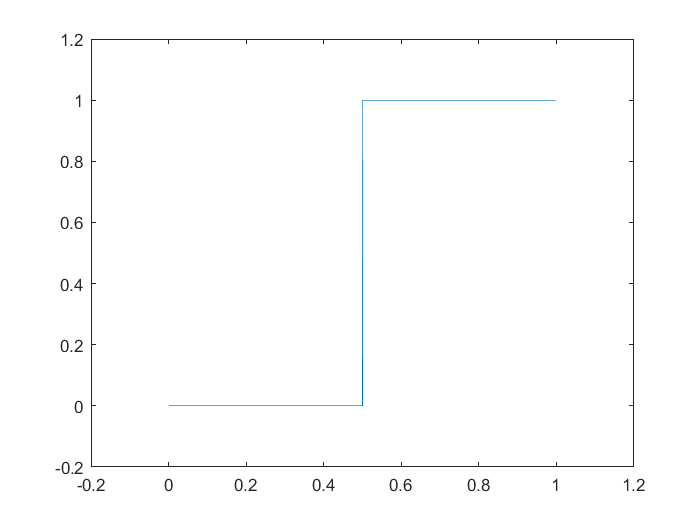

clear; clc;
dx = 0.001;
L = 1;
x = dx:dx:L;

fx = ones(size(x));
fx(1:length(x)/2) = 0;
plot(x,fx);
axis([-0.2 1.2 -0.2 1.2]); 

## Approximation

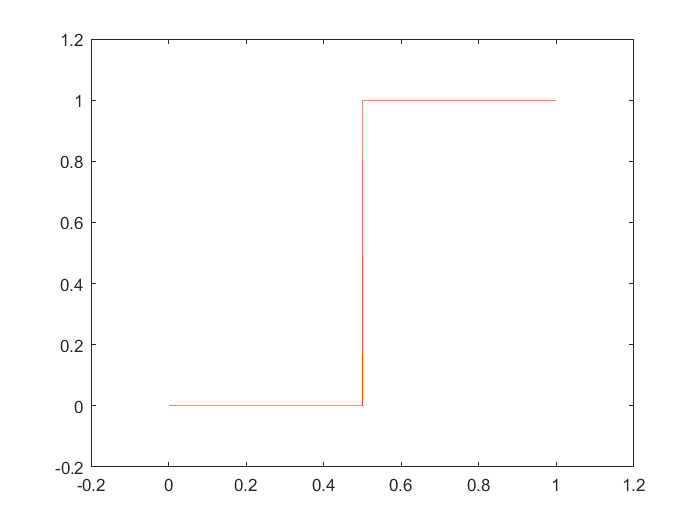

A0 = (2/L) * sum(fx.*cos(2*pi*0*x/L)) * dx;
ffs = A0/2;
for n=1:500
    hold off;
    plot(x,fx);
    axis([-0.2 1.2 -0.2 1.2]);    

    An = (2/L) * sum(fx.*cos(2*pi*n*x/L)) * dx;
    Bn = (2/L) * sum(fx.*sin(2*pi*n*x/L)) * dx;
    ffs = ffs + An*cos(2*pi*n*x/L) + Bn*sin(2*pi*n*x/L);
    
    hold on;
    plot(x,ffs);
    drawnow;
    pause(0.05);
end